# ME2801: Time Response with MATALB

In addition to Nise Appendix B - MATLAB Tutorial

MATLAB has tools for

- Representing a transfer function: `tf()`, `zpk()`

- Finding polynomial roots: `roots()`

- Plotting the response: `step(), impulse()`

- Plotting the poles and zeros

- Finding system metrics: `stepinfo()`, `damp()`

First order system model

Canonical form


$$G_1( s ) = K_{DC} \frac{ a }{ s+a } = K_{DC} \frac{ 1 }{ \tau s + 1 }$$


Form of the step reponse


$$c(t) = K_{DC} \, \left(1-e^{-t/\tau} \, \right)$$


clear
G1 = tf(1, [20 1])

G1 =
 
     1
  --------
  20 s + 1
 
Continuous-time transfer function.
Model Properties


#### What are the poles and zeros?

pp =pole(G1)

pp = -0.0500

zz =zero(G1)

zz =
  0×1 empty double column vector


[z, p, k] = zpkdata(G1)

z = 1×1 cell array
    {0×1 double}

p = 1×1 cell array
    {[-0.0500]}

k = 0.0500

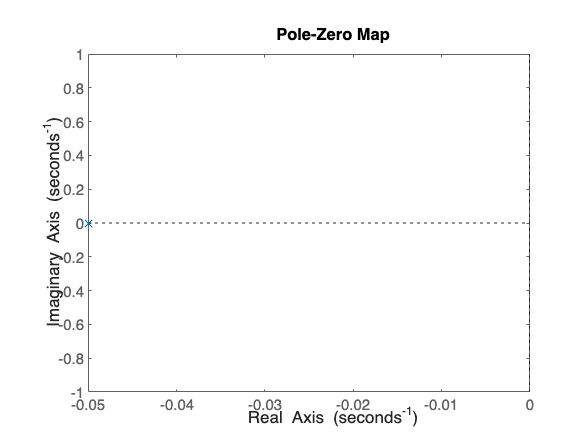

pzmap(G1)

####  Identify system parameters

- Time constant: $\tau$

damp(G1)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -5.00e-02     1.00e+00       5.00e-02         2.00e+01    


#### Plot responses to test signals

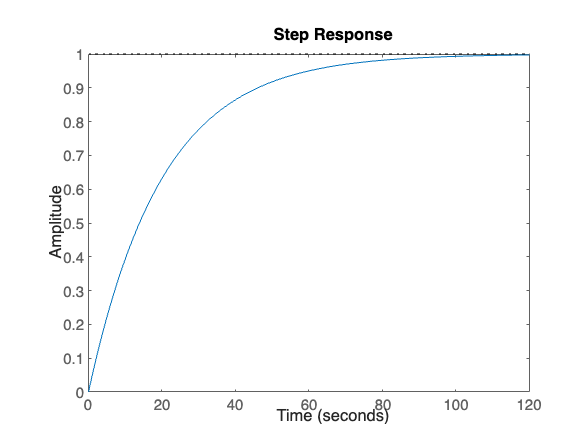

figure(1);
clf();
step(G1)

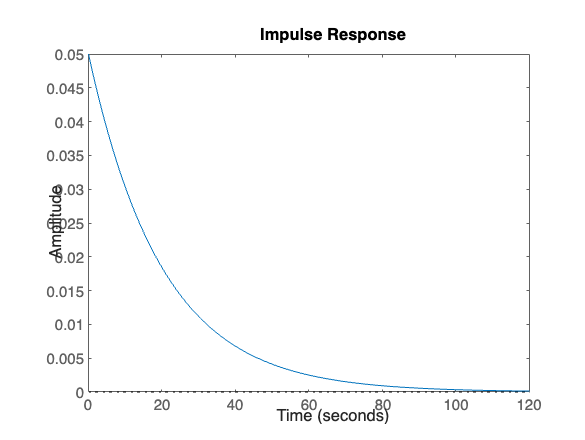


figure(2);
clf();
impulse(G1)

#### Find response metrics

si = stepinfo(G1)

si = struct with fields:
         RiseTime: 43.9401
    TransientTime: 78.2415
     SettlingTime: 78.2415
      SettlingMin: 0.9045
      SettlingMax: 0.9993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9993
         PeakTime: 146.4444

Tr = si.RiseTime

Tr = 43.9401

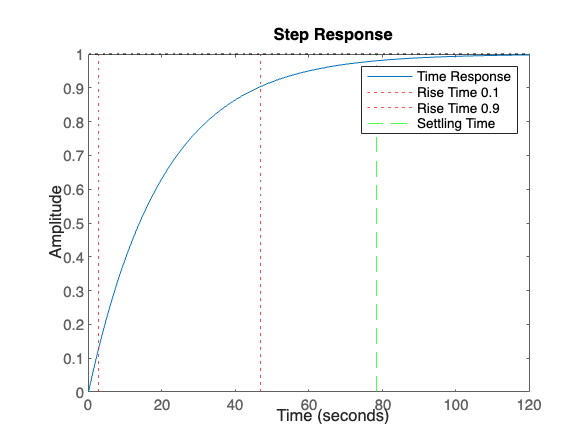


figure(1)
hold on
[yy, tt] = step(G1);
t0 = tt(find(yy>=0.1,1));
xline(t0,'r:')
xline(t0+Tr,'r:')
xline(si.SettlingTime, 'g--')
legend("Time Response", "Rise Time 0.1", "Rise Time 0.9", "Settling Time")

## Second order underdamped system model

Canonical form


$$G_2(s) = K_{DC}\frac{ \left( \mathcal{R}^2 + \mathcal{I}^2 \right)}{(s + \mathcal{R})^2 + \mathcal{I}^2} = 
K_{DC} \frac{\left( (\zeta \omega_n)^2 + \omega_d^2 \right)}{(s + \zeta \omega_n)^2 + \omega_d^2} =
K_{DC} \frac{\omega_n^2}{s^2 + 2 \zeta \omega_n s + \omega_n^2}$$


Form of the step response


$$ c(t)  =  K[1-A \, e^{-\zeta \omega_n \,t} \cos(\omega_d \,t - \phi)] \$$


% Complex poles
p1=[1 complex(3, 7)];
p2=[1 complex(3, -7)];
% Create a TF
num = 58;
den = conv(p1, p2);
G2 = tf(num, conv(p1,p2))

G2 =
 
        58
  --------------
  s^2 + 6 s + 58
 
Continuous-time transfer function.
Model Properties


#### What are the poles and zeros?

pp = pole(G2)

pp =   -3.0000 + 7.0000i
  -3.0000 - 7.0000i


pr = roots(den)

pr =   -3.0000 + 7.0000i
  -3.0000 - 7.0000i



zz = zero(G2)

zz =
  0×1 empty double column vector


zr = roots(num)

zr =
  0×1 empty double column vector



[z, p, k] = zpkdata(G2)

z = 1×1 cell array
    {0×1 double}

p = 1×1 cell array
    {2×1 double}

k = 58

p{1}

ans =   -3.0000 + 7.0000i
  -3.0000 - 7.0000i


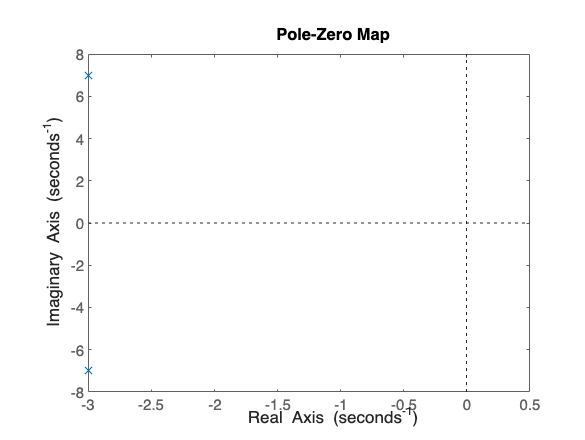


figure(3);
clf();
pzmap(G2)

####  Identify system parameters

- Undamped natural frequency: $\omega_n$

- Daming ratio: $
\zeta$

- Damped natural frequency: $\omega_d = \mathcal{I} = \sqrt{1-\zeta^2} \, \omega_n$

damp(G2)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -3.00e+00 + 7.00e+00i     3.94e-01       7.62e+00         3.33e-01    
 -3.00e+00 - 7.00e+00i     3.94e-01       7.62e+00         3.33e-01    


#### Plot responses to test signals

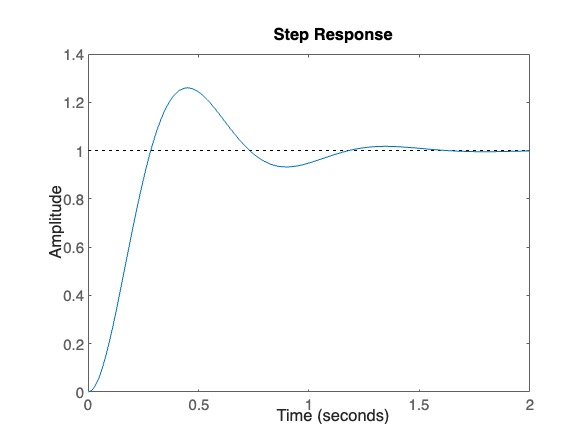

figure(4);
clf();
step(G2)

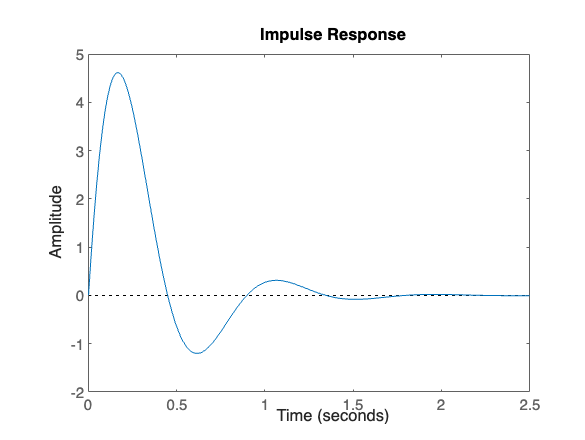


figure(5)
impulse(G2)

#### Step response metrics

si = stepinfo(G2)

si = struct with fields:
         RiseTime: 0.1912
    TransientTime: 1.1043
     SettlingTime: 1.1043
      SettlingMin: 0.9262
      SettlingMax: 1.2601
        Overshoot: 26.0076
       Undershoot: 0
             Peak: 1.2601
         PeakTime: 0.4452

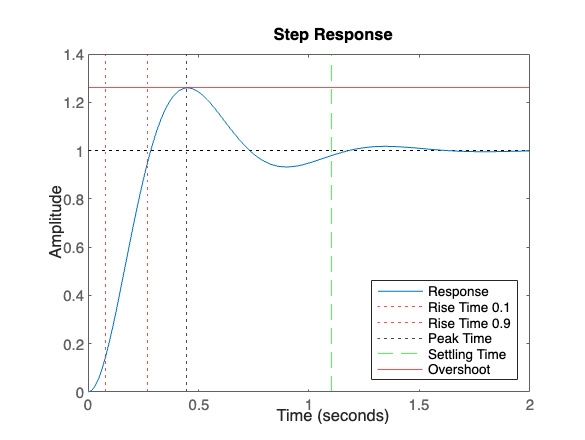


figure(4)
hold on;
[yy, tt] = step(G2);
t0 = tt(find(yy>=0.1,1));
xline(t0,'r:')
xline(t0+si.RiseTime,'r:')
xline(si.PeakTime, 'k:')
xline(si.SettlingTime, 'g--')
yline(1+si.Overshoot/100,'r-')
legend("Response",  "Rise Time 0.1", "Rise Time 0.9", "Peak Time",  ...
    "Settling Time","Overshoot", "Location", "southeast")